## IMPORT LIBRARY

addpath('/Users/simone/Documents/MATLAB/R1/LIBRARY/')  
savepath /Users/simone/Documents/MATLAB/R1/LIBRARY/pathdef.m

# DIRECT KINEMATIC 

A manipulator can be schematically represented from a mechanical viewpoint as a kinematic chain of rigid bodies (links) connected by means of revolute or prismatic joints. One end of the chain is constrained to a base, while an end-effector is mounted to the other end. 

Direct kinematics equation allows the end-effector position and orientation (pose) to be expressed as a function of the joint variables of the mechanical structure with respect to a reference frame.  

- functional aspects: definition of robot **workspace** and **calibration** 

- operational aspects: link the **task execution space** with the **task definition space** ( trajectory planning, programming, motion control)

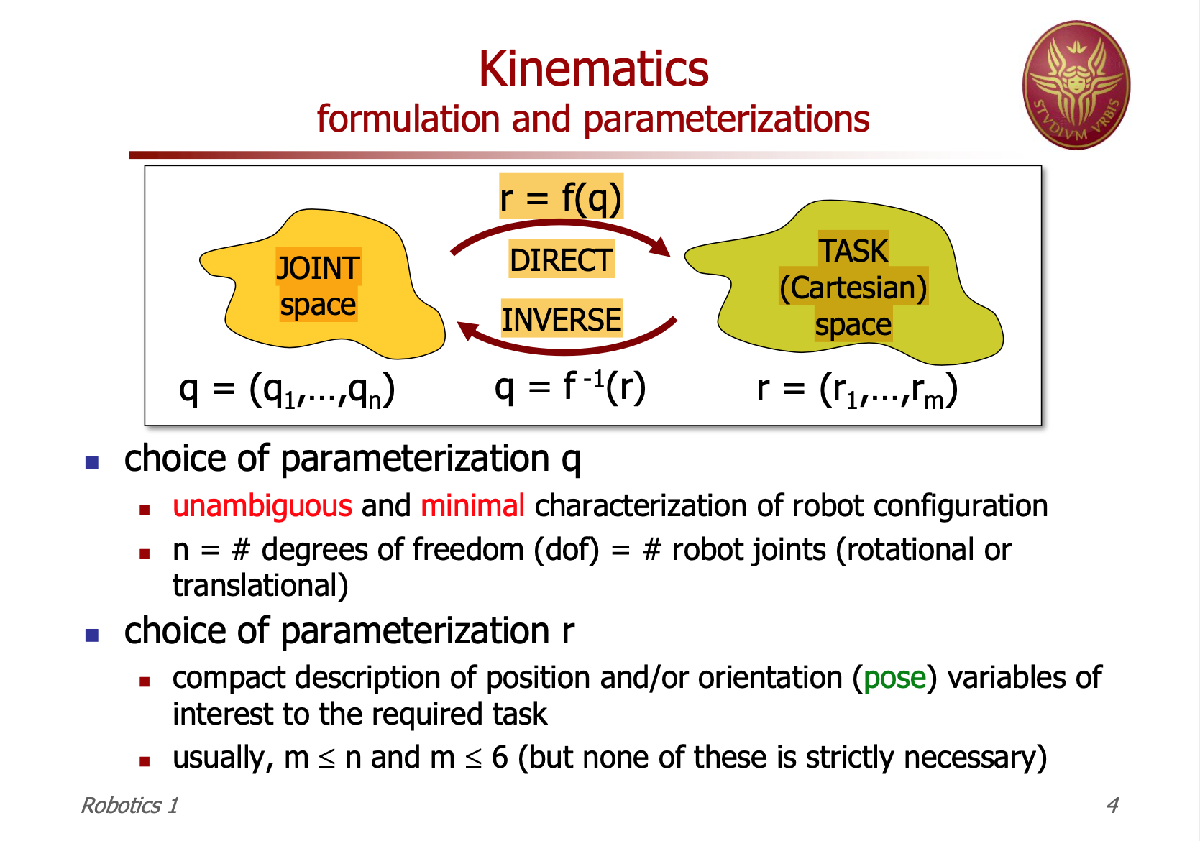

# DENAVITH-HARTENGERG APPROACH

POSSIBLE EXERCISE: GIVEN A CONFIGURATION Q, FIND P IN RF0 WHERE P IS GIVEN IN RF7 IN HOMOGENEOUS COORDINATES

pd=[0 0.05 0.1 1]'

p_0 = T * pd (FIRST COMPUTE T)

OR

for i=length(A_list):-1:1

    p_0 = A_list{i} * p_0; (DINAMICALLY COMPUTE P0)

end

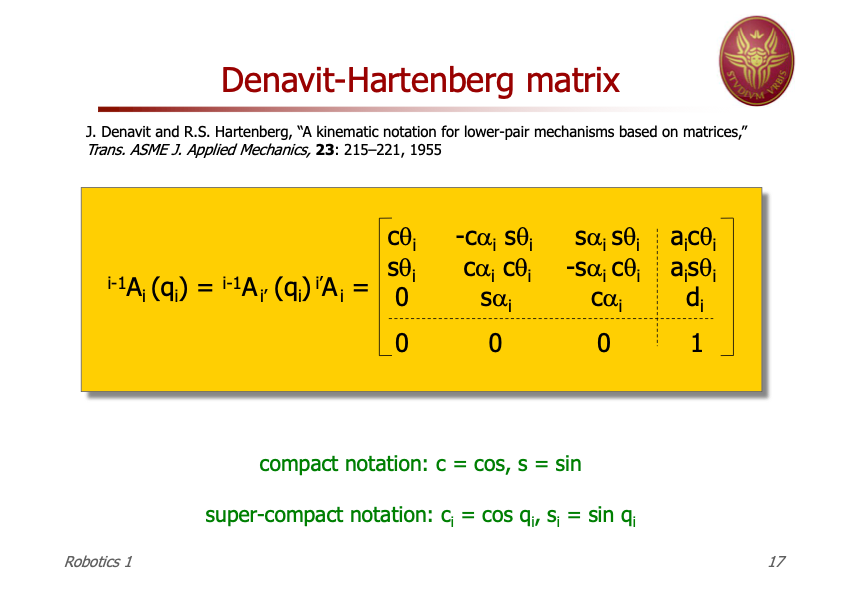

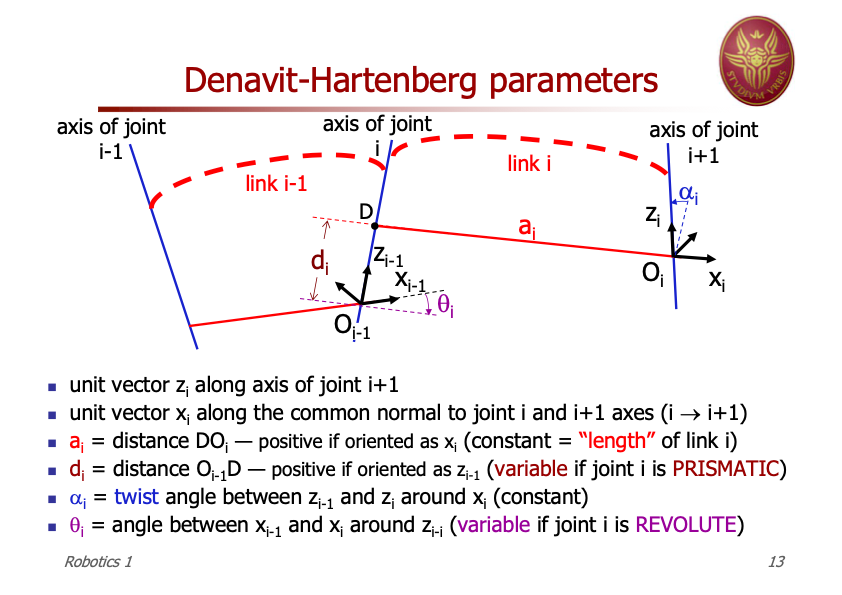

syms alpha1 a1 d1 q1
syms alpha2 a2 d2 q2
syms alpha3 a3 d3 q3
syms alpha4 a4 d4 q4
syms alpha5 a5 d5 q5
syms alpha6 a6 d6 q6
syms alpha7 a7 d7 q7

warning('off','all')

# 2 LINK PLANAR ARM (2R)

disp('2 LINK PLANAR ARM (2R)')

2 LINK PLANAR ARM (2R)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = [ ...
    0   a1  0   q1;
    0   a2  0   q2];

SR_ROBO.showDHTable(DH_table_)

    joint_i    alpha_i     a_i       d_i     theta_i
    _______    _______    ______    _____    _______

       1        {'0'}     {'a1'}    {'0'}    {'q1'} 
       2        {'0'}     {'a1'}    {'0'}    {'q2'} 




[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,true);

A1 =


$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & a_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & a_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2 =


$$\left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & a_{1}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & a_{1}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T02 =


$$\left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & 0 & a_{1}\,\left(\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & 0 & a_{1}\,\left(\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


type

type = 1×2 cell array
    {'r'}    {'r'}


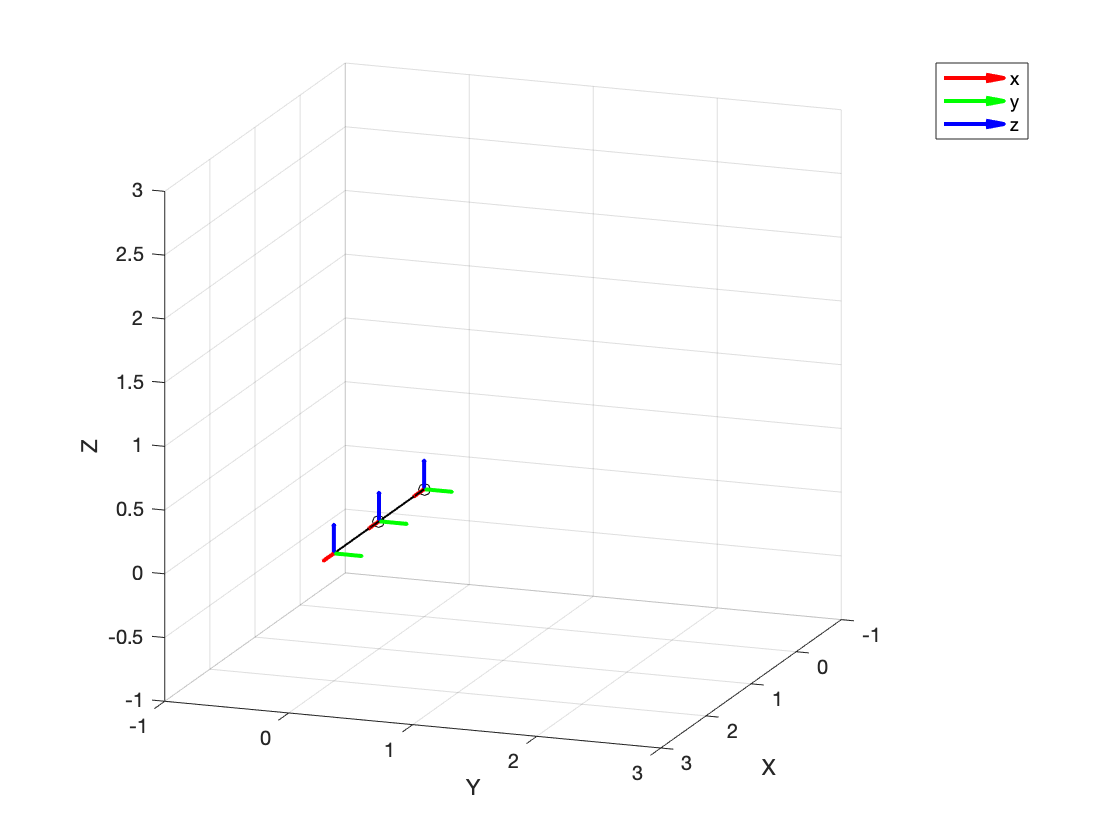


% DIRECT KINEMATIC
old = { a1, a2, q1, q2};

new = { 1, 1, 0, 0};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);

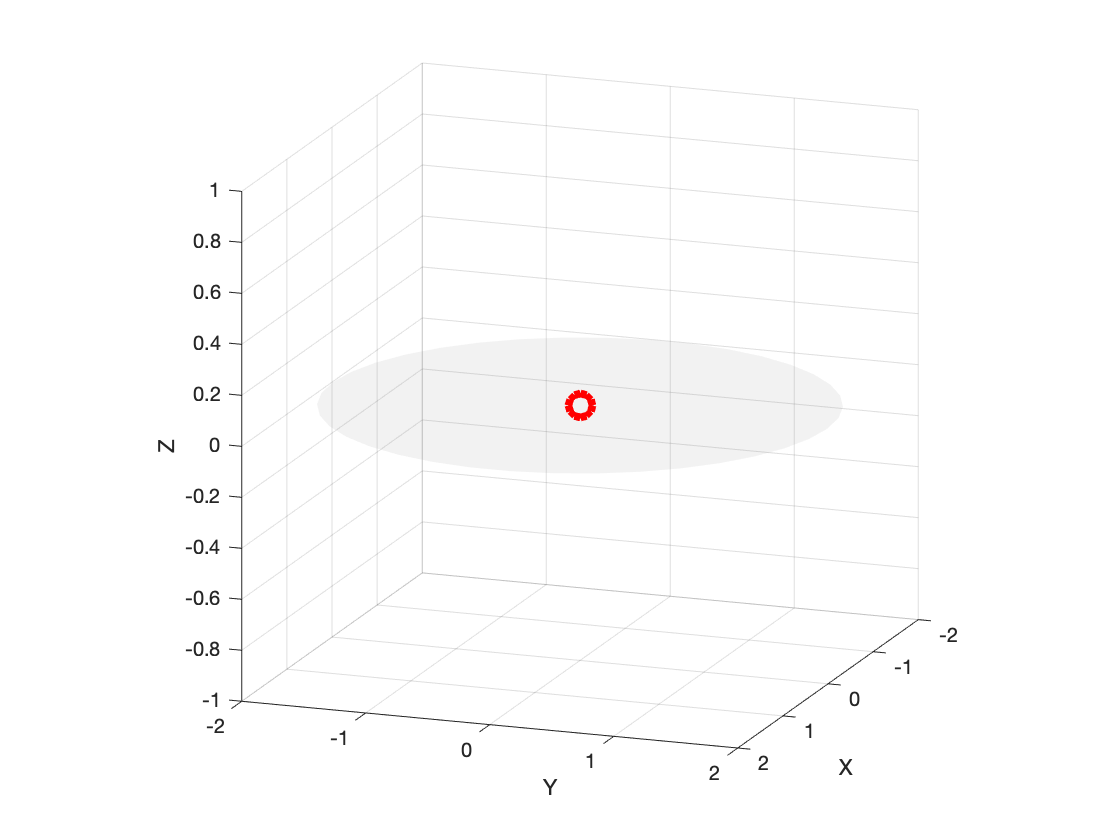


% JOINT LIMITS
t1=linspace(-180,180,20)*pi/180;
t2=linspace(-180,180,20)*pi/180;
[t1,t2]=ndgrid(t1,t2);
old = { a1, a2, q1, q2};
new = { 1, 1, t1, t2};

% PLOT WORKSPACE
SR_ROBO.workspace(T_sym,old,new);

WORKSPACE: M=2 N=2

W1 reachable workspace (all reachable reigions)

W2 dexterous workspace (all reachable reigions with ALL different kinematic solutions)

W2 subset of W1

IF L1=L2=L: W1={p≤2L, p in R^2}, W2={p=0} infinite set 

IF L1>L2: W1={|L1-L2| ≤ p ≤ |L1+L2|}, W2=void

IF L1=L2=L:

  - if p<2L -> 2 REGULAR SOLUTIONS (IN W1)

  - if p=2L -> 1 SOLUTION, 1 SINGULAR (IN W1)

  - if p=0  -> inf^1 SINGULAR SOLUTIONS (IN W2)

# 3 LINK PLANAR ARM (3R)

disp('3 LINK PLANAR ARM (3R)')

3 LINK PLANAR ARM (3R)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = ...
    [0   a1  0   q1;
    0   a2  0   q2;
    0   a3  0   q3];

SR_ROBO.showDHTable(DH_table_)

    joint_i    alpha_i     a_i       d_i     theta_i
    _______    _______    ______    _____    _______

       1        {'0'}     {'a1'}    {'0'}    {'q1'} 
       2        {'0'}     {'a2'}    {'0'}    {'q2'} 
       3        {'0'}     {'a3'}    {'0'}    {'q3'} 



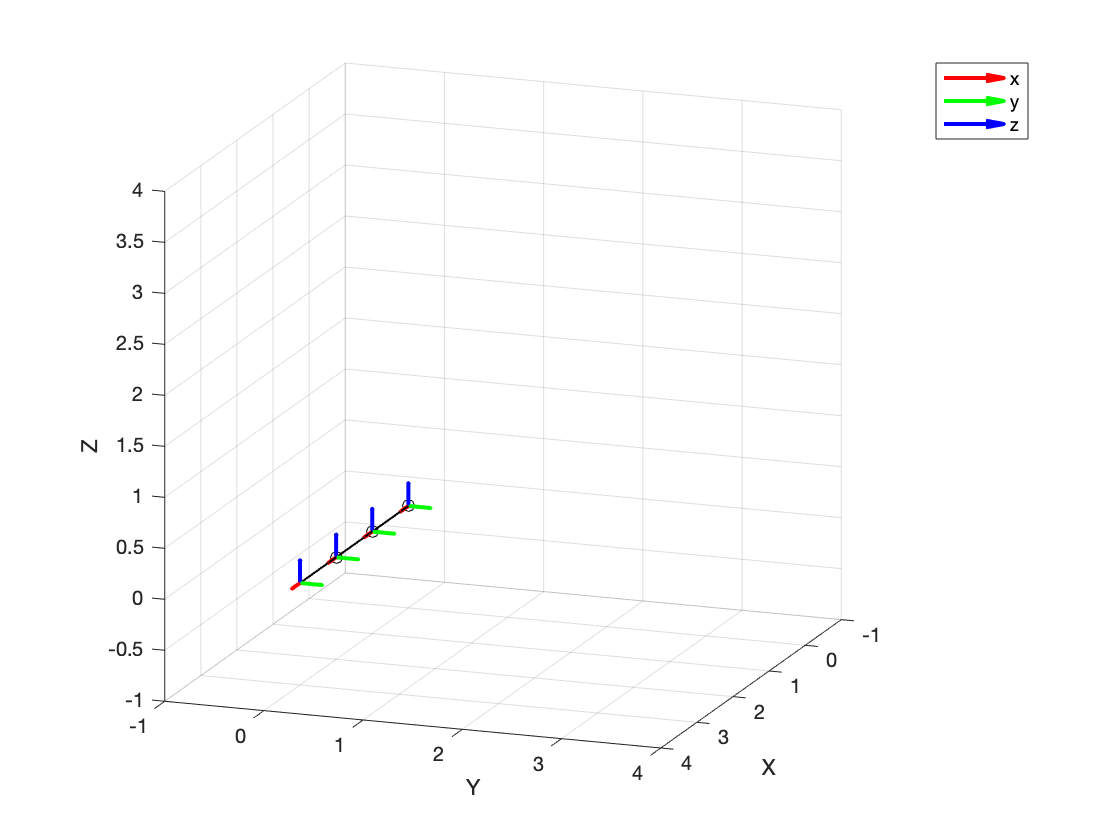


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { a1, a2, a3, q1, q2, q3};

new = { 1, 1, 1, 0, 0, 0};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);

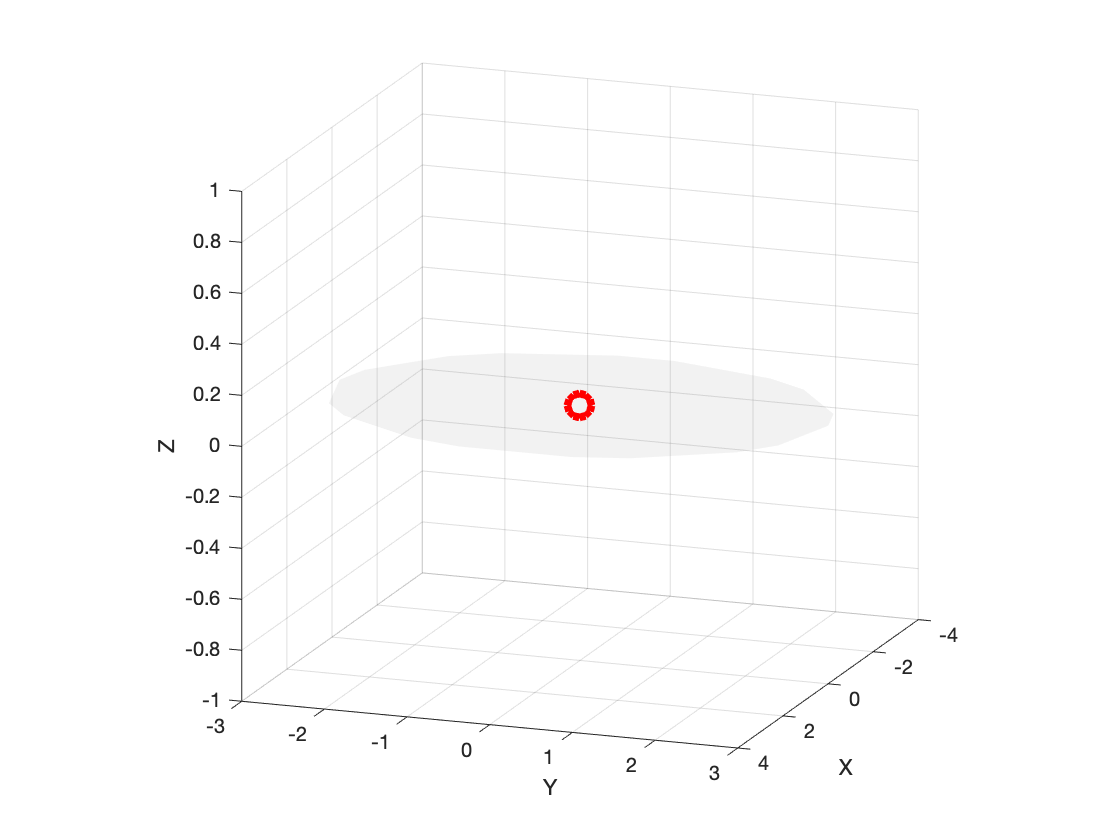


% JOINT LIMITS
t1=linspace(-180,180,10)*pi/180;
t2=linspace(-180,180,10)*pi/180;
t3=linspace(-180,180,10)*pi/180;
[t1,t2,t3]=ndgrid(t1,t2,t3);
old = { a1, a2, a3, q1, q2, q3};
new = { 1, 1, 1, t1, t2, t3};

% PLOT WORKSPACE
SR_ROBO.workspace(T_sym,old,new);

WORKSPACE: M=2 N=3 REDUNDANT

W1 reachable workspace (all reachable reigions)

W2 dexterous workspace (all reachable reigions with ALL different kinematic solutions)

W2 subset of W1

INF^(N-M) set of SOLUTIONS

If L1=L2=3L=L: W1={p≤3L, p in R^2}, W2={p≤L, p in R^2}

In W1:

  - if L<p<3L -> inf^1 SOLUTIONS, NEVER SINGULAR

  - if p=3L -> 1 SOLUTION, 1 SINGULAR

  - if p=L  -> inf^1 SOLUTIONS, 3 SINGULAR

  - if p<L  -> inf^1 SOLUTIONS, NEVER SINGULAR

# ANTROPOMORPHIC ARM (3R)

disp('ANTROPOMORPHIC ARM (3R)')

ANTROPOMORPHIC ARM (3R)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = ...
    [sym(pi/2)  0  d1   q1;
    0   a2  0   q2;
    0   a3  0   q3];

SR_ROBO.showDHTable(DH_table_)

    joint_i    alpha_i      a_i       d_i      theta_i
    _______    ________    ______    ______    _______

       1       {'pi/2'}    {'0' }    {'d1'}    {'q1'} 
       2       {'0'   }    {'a2'}    {'0' }    {'q2'} 
       3       {'0'   }    {'a3'}    {'0' }    {'q3'} 



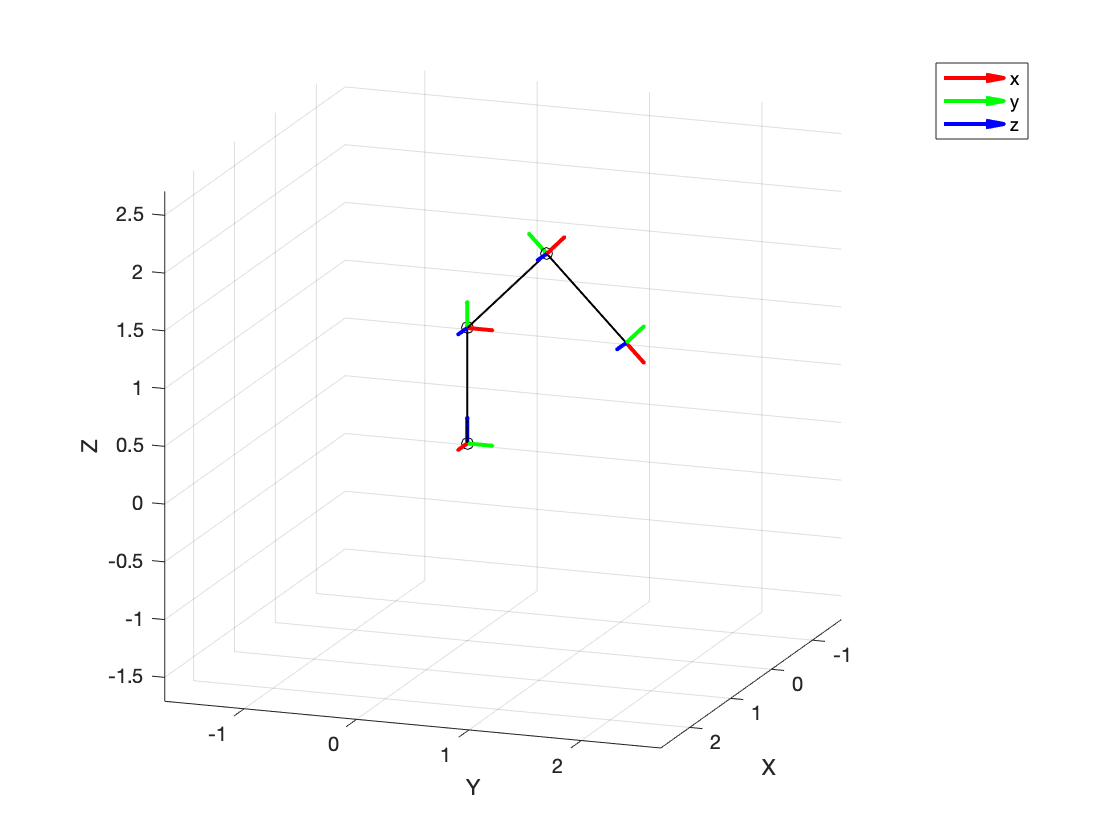


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { d1, a2, a3, q1, q2, q3};

new = { 1, 1, 1, pi/2, pi/4, -pi/2};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);

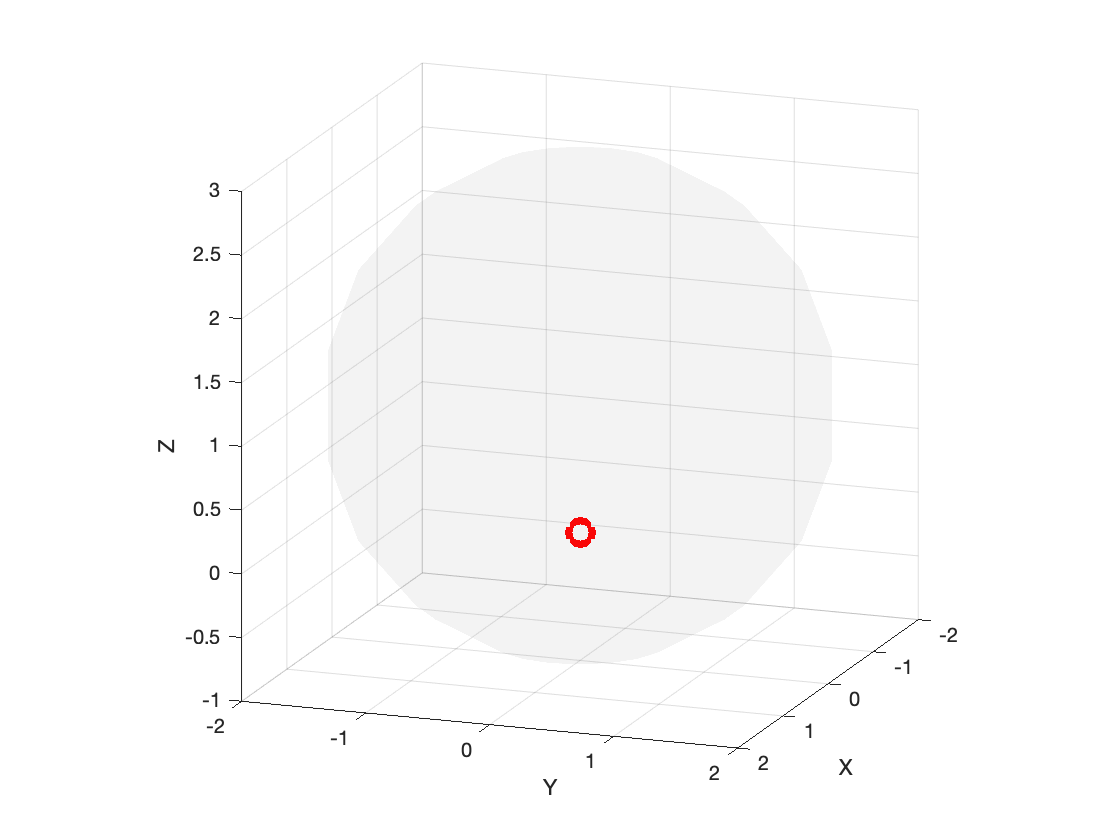


% JOINT LIMITS
t1=linspace(-180,180,10)*pi/180;
t2=linspace(-180,180,10)*pi/180;
t3=linspace(-180,180,10)*pi/180;
[t1,t2,t3]=ndgrid(t1,t2,t3);
old = { d1, a2, a3, q1, q2, q3};
new = { 1, 1, 1, t1, t2, t3};

% PLOT WORKSPACE
SR_ROBO.workspace(T_sym,old,new);

# POLAR ROBOT (2R P)

disp('POLAR ROBOT (2R P)')

POLAR ROBOT (2R P)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = ...
    [sym(-pi/2)   0  d1   q1;
    sym(pi/2)   0  0   q2;
    0   0  q3   0];

SR_ROBO.showDHTable(DH_table_)

    joint_i     alpha_i      a_i      d_i      theta_i
    _______    _________    _____    ______    _______

       1       {'-pi/2'}    {'0'}    {'d1'}    {'q1'} 
       2       {'pi/2' }    {'0'}    {'0' }    {'q2'} 
       3       {'0'    }    {'0'}    {'q3'}    {'0' } 



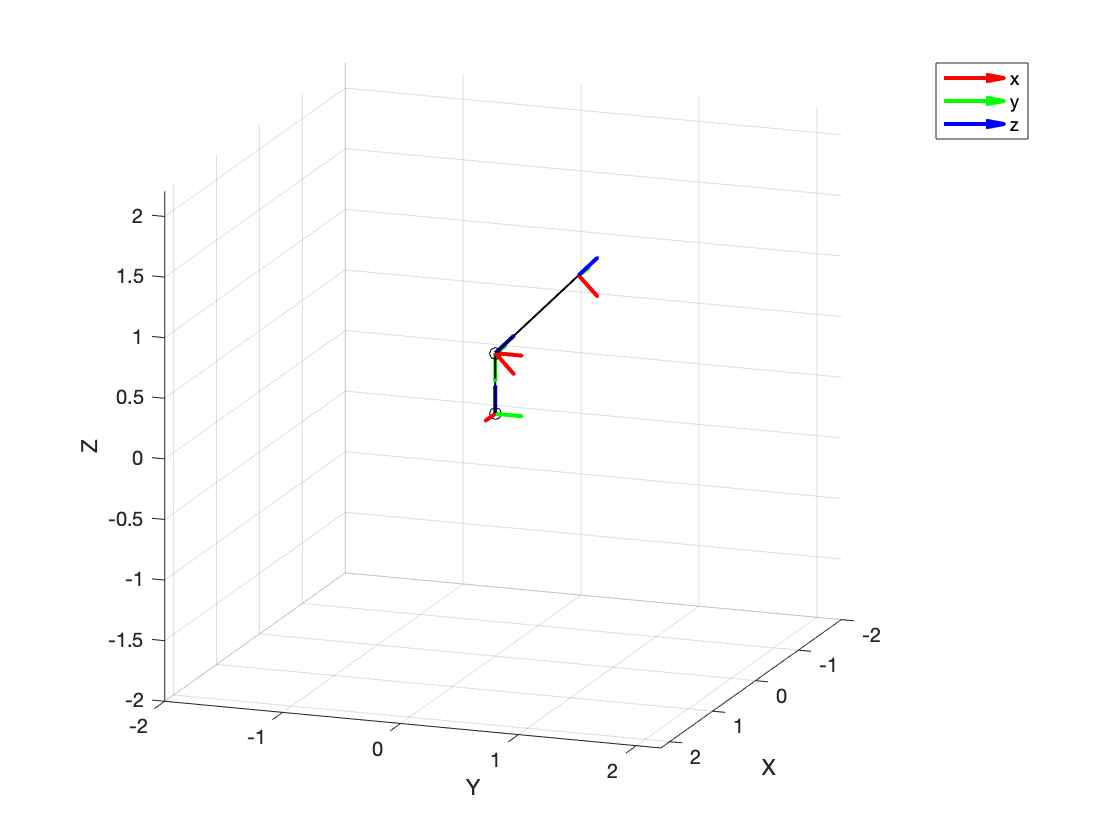


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { d1, q1, q2, q3};

new = { 0.5, pi/2, pi/4, 1};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);

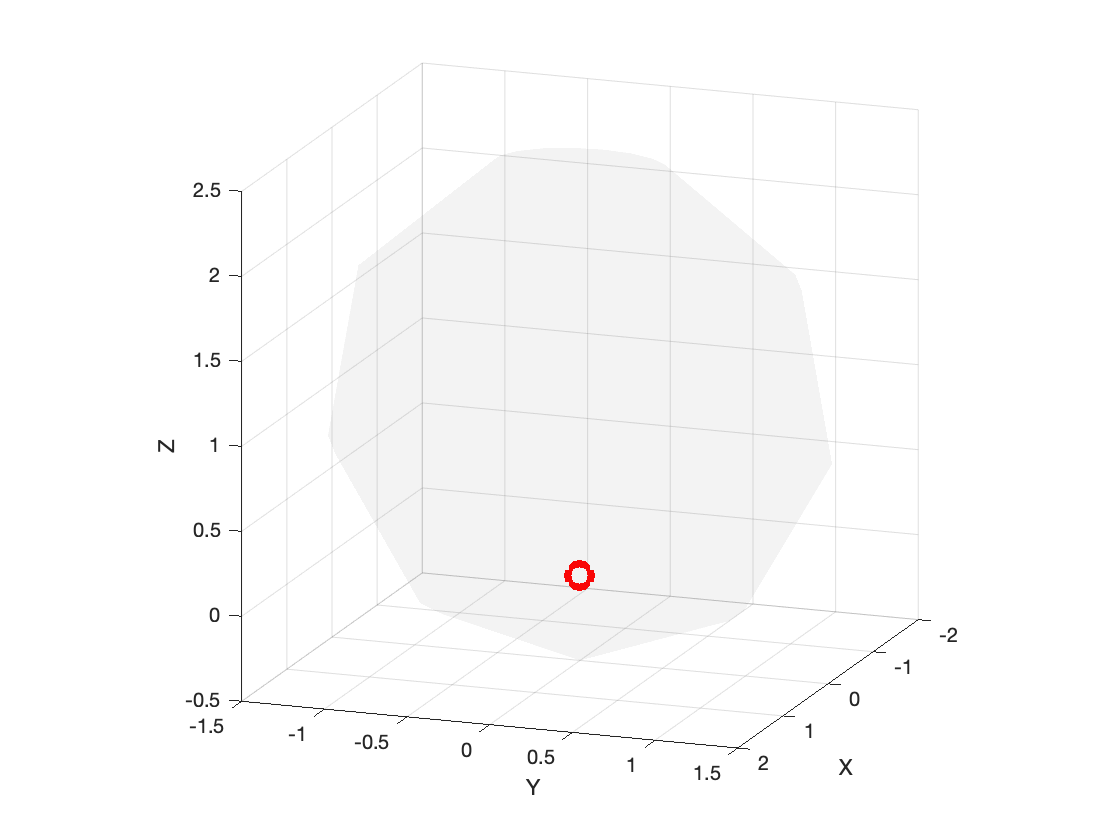


% JOINT LIMITS
t1=linspace(-180,180,10)*pi/180;
t2=linspace(-180,180,10)*pi/180;
t3=linspace(0,1.5,10);
[t1,t2,t3]=ndgrid(t1,t2,t3);
old = { d1, q1, q2, q3};
new = { 1, t1, t2, t3};

% PLOT WORKSPACE
SR_ROBO.workspace(T_sym,old,new);

# SCARA ROBOT (2R P R)

disp('SCARA ROBOT (2R P R)')

SCARA ROBOT (2R P R)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = [ ...
    0       a1  d1  q1;
    0       a2  0   q2;
    0       0   q3  0;
    sym(pi) 0   d4  q4];

SR_ROBO.showDHTable(DH_table_)

    joint_i    alpha_i     a_i       d_i      theta_i
    _______    _______    ______    ______    _______

       1       {'0' }     {'a1'}    {'d1'}    {'q1'} 
       2       {'0' }     {'a2'}    {'0' }    {'q2'} 
       3       {'0' }     {'0' }    {'q3'}    {'0' } 
       4       {'pi'}     {'0' }    {'d4'}    {'q4'} 



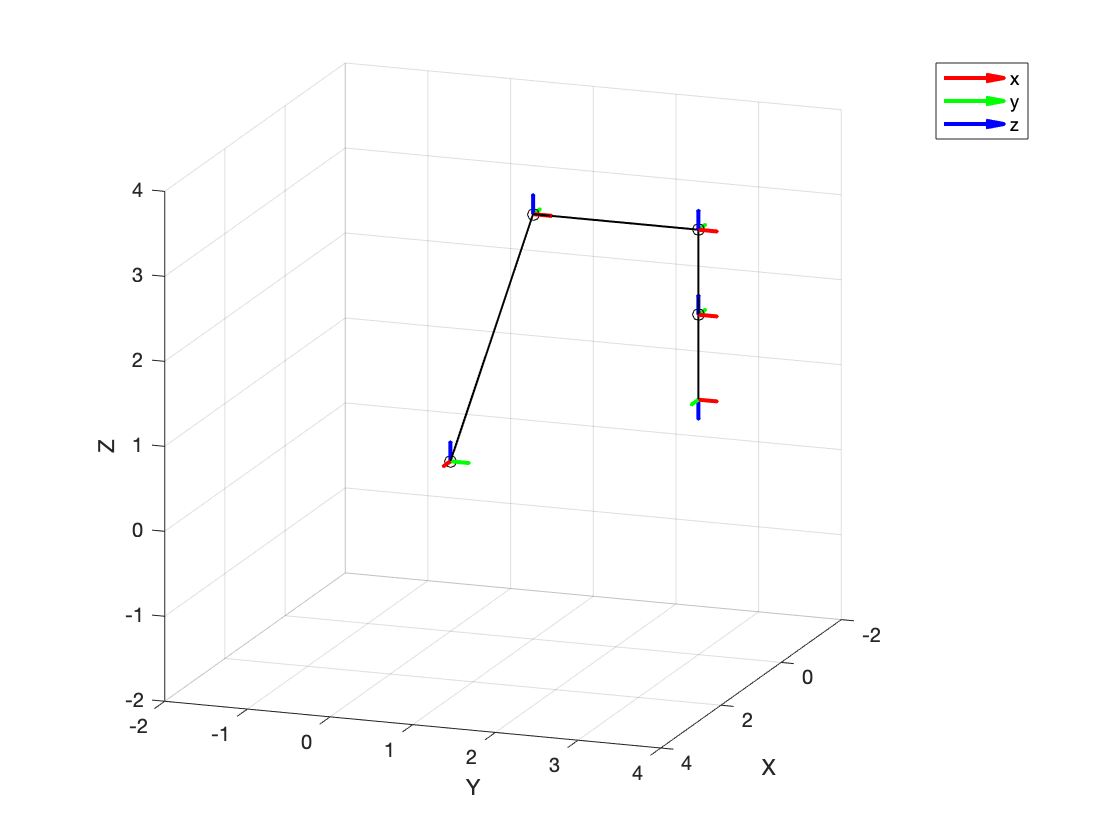


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { a1, a2, d1, d4, q1, q2, q3, q4};

new = { 1, 2, 3, -1, pi/2, 0, -1, 0};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);

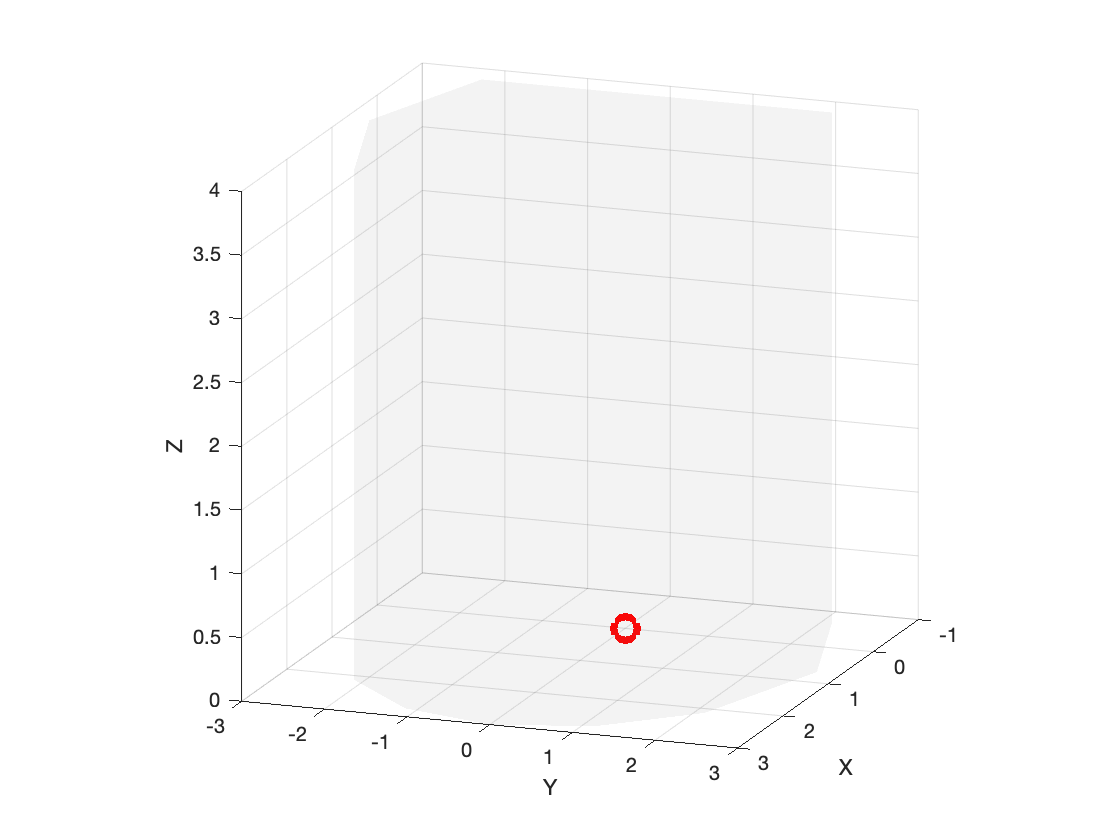


% JOINT LIMITS
t1=linspace(-45,45,5)*pi/180;
t2=linspace(-90,90,5)*pi/180;
t3=linspace(-2,2,5);
t4=linspace(-180,180,5)*pi/180;
[t1,t2,t3,t4]=ndgrid(t1,t2,t3,t4);
old = { a1, a2, d1, d4, q1, q2, q3, q4};
new = { 1, 2, 3, -1, t1, t2, t3, t4};

% PLOT WORKSPACE
SR_ROBO.workspace(T_sym,old,new);

# STANDFORD MANIPULATOR (2R P 3R)

disp('STANDFORD MANIPULATOR (2R P 3R)')

STANDFORD MANIPULATOR (2R P 3R)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = [ ...
    sym(-pi/2)  0   d1  q1;
    sym(pi/2)   0   d2  q2;
    0           0   q3  sym(-pi/2);
    sym(-pi/2)  0   0   q4;
    sym(pi/2)   0   0   q5;
    0           0   d6  q6];

SR_ROBO.showDHTable(DH_table_)

    joint_i     alpha_i      a_i      d_i       theta_i 
    _______    _________    _____    ______    _________

       1       {'-pi/2'}    {'0'}    {'d1'}    {'q1'   }
       2       {'pi/2' }    {'0'}    {'d2'}    {'q2'   }
       3       {'0'    }    {'0'}    {'q3'}    {'-pi/2'}
       4       {'-pi/2'}    {'0'}    {'0' }    {'q4'   }
       5       {'pi/2' }    {'0'}    {'0' }    {'q5'   }
       6       {'0'    }    {'0'}    {'d6'}    {'q6'   }



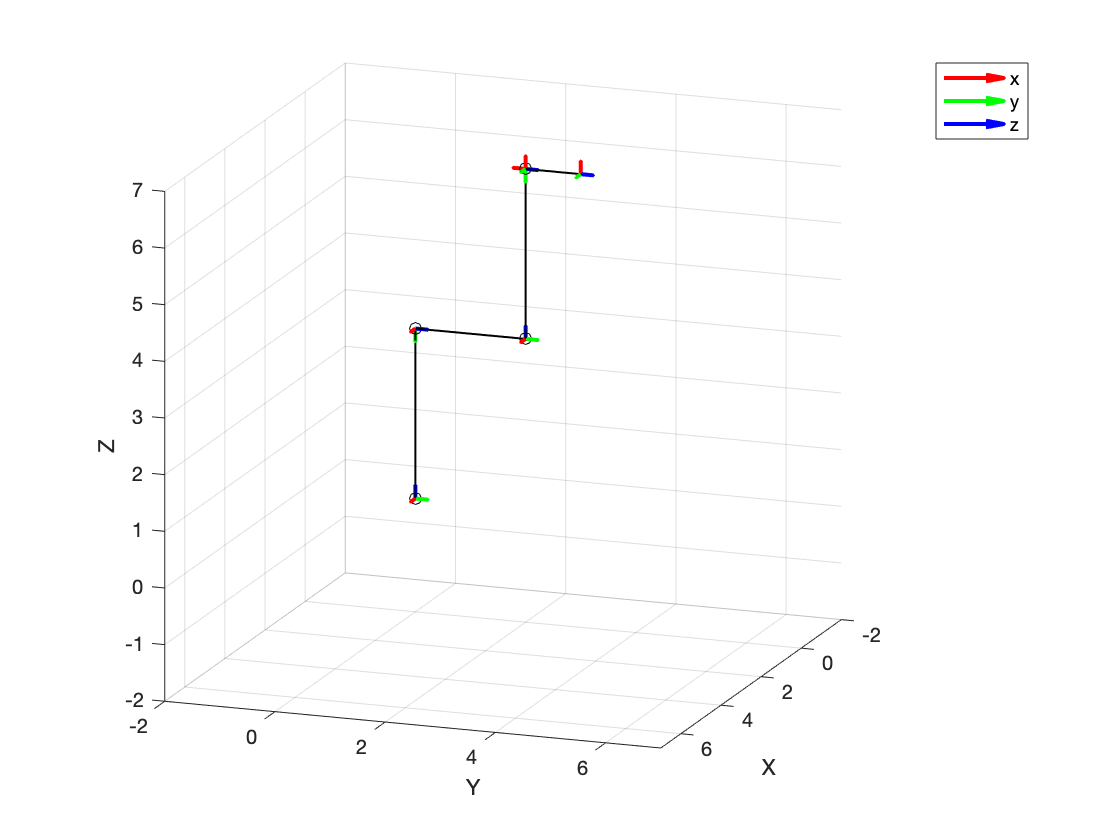


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { d1, d2, d6, q1, q2, q3, q4, q5, q6};

new = { 3, 2, 1, 0, 0, 3, 0, -pi/2, 0};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);

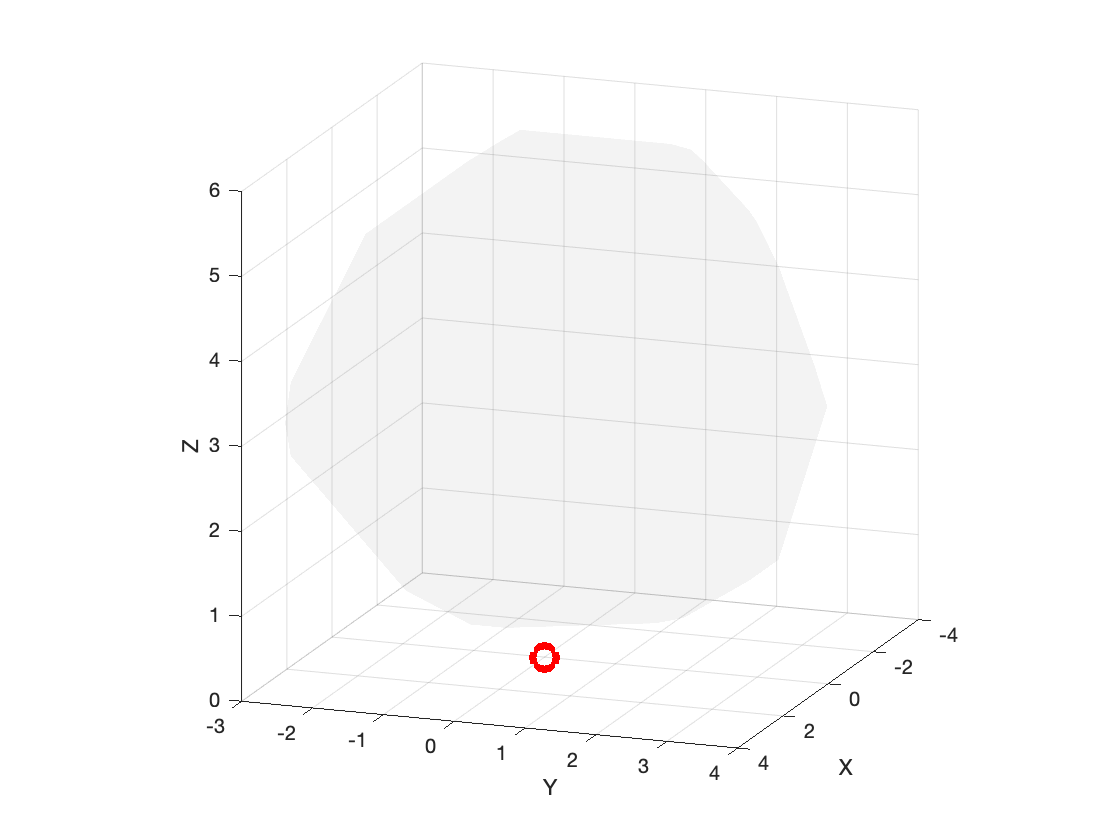


% JOINT LIMITS
t1=linspace(-90,90,4)*pi/180;
t2=linspace(-90,90,4)*pi/180;
t3=linspace(-2,2,4);
t4=linspace(-180,180,4)*pi/180;
t5=linspace(-90,90,4)*pi/180;
t6=linspace(-90,90,4)*pi/180;
[t1,t2,t3,t4,t5,t6]=ndgrid(t1,t2,t3,t4,t5,t6);
old = { d1, d2, d6, q1, q2, q3, q4, q5, q6};
new = { 3, 2, 1, t1, t2, t3, t4, t5, t6};

% PLOT WORKSPACE
SR_ROBO.workspace(T_sym,old,new);

# UNIMATION PUMA 600 (6R)

disp('UNIMATION PUMA 600 (6R)')

UNIMATION PUMA 600 (6R)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = [...
    sym(-pi/2)  0   0   q1;
    0           a2  0   q2;
    sym(pi/2)   a2  d3  q3;
    sym(-pi/2)  0   d4  q4;
    sym(pi/2)   0   0   q5;
    0           0   0   q6];

SR_ROBO.showDHTable(DH_table_)

    joint_i     alpha_i      a_i       d_i      theta_i
    _______    _________    ______    ______    _______

       1       {'-pi/2'}    {'0' }    {'0' }    {'q1'} 
       2       {'0'    }    {'a2'}    {'0' }    {'q2'} 
       3       {'pi/2' }    {'a2'}    {'d3'}    {'q3'} 
       4       {'-pi/2'}    {'0' }    {'d4'}    {'q4'} 
       5       {'pi/2' }    {'0' }    {'0' }    {'q5'} 
       6       {'0'    }    {'0' }    {'0' }    {'q6'} 



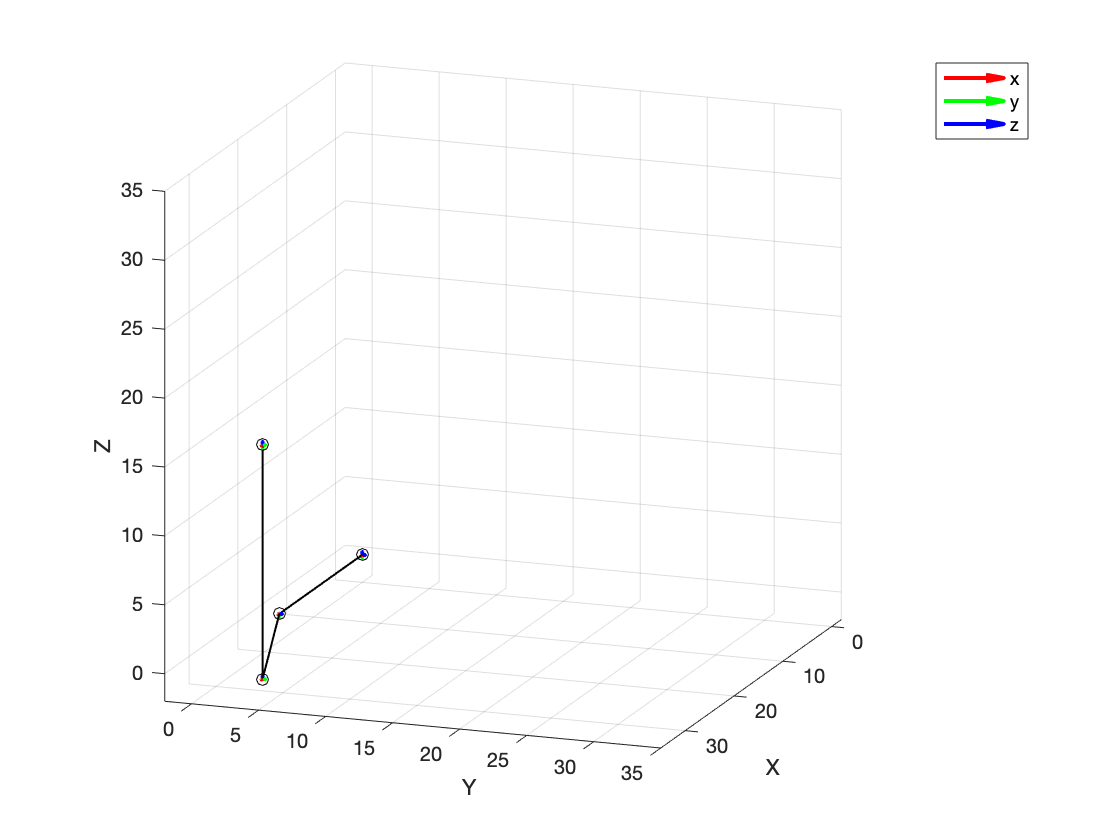


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { a2, a3, d3, d4, q1, q2, q3, q4, q5, q6};

new = { 17, 0.75, 4.937, 17, 0, 0, 0, 0, 0, 0};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);

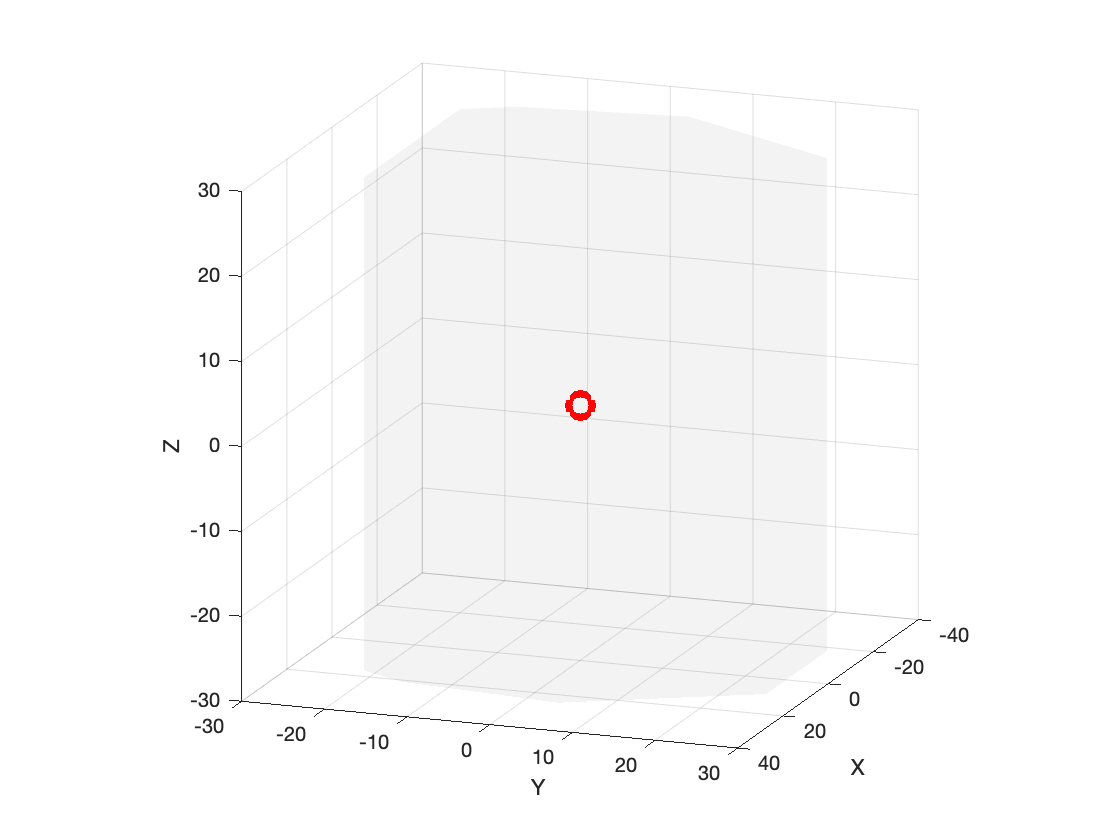


% JOINT LIMITS
t1=linspace(-160,160,4)*pi/180;
t2=linspace(-225,45,4)*pi/180;
t3=linspace(-45,225,4)*pi/180;
t4=linspace(-170,170,4)*pi/180;
t5=linspace(-135,135,4)*pi/180;
t6=linspace(-170,170,4)*pi/180;
[t1,t2,t3,t4,t5,t6]=ndgrid(t1,t2,t3,t4,t5,t6);
old = { a2, a3, d3, d4, q1, q2, q3, q4, q5, q6};
new = { 17, 0.75, 4.937, 17, t1,t2,t3,t4,t5,t6};

% PLOT WORKSPACE
SR_ROBO.workspace(T_sym,old,new);

# KUKA LWR 4+ (7R)

disp('KUKA LWR 4+ (7R)')

KUKA LWR 4+ (7R)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = [...
    sym(pi/2)   0   0   q1;
    sym(-pi/2)  0   0   q2;
    sym(-pi/2)  0   d3  q3;
    sym(pi/2)   0   0   q4;
    sym(pi/2)   0   d5  q5;
    sym(-pi/2)  0   0   q6;
    0           0   0   q7];

SR_ROBO.showDHTable(DH_table_)

    joint_i     alpha_i      a_i      d_i      theta_i
    _______    _________    _____    ______    _______

       1       {'pi/2' }    {'0'}    {'0' }    {'q1'} 
       2       {'-pi/2'}    {'0'}    {'0' }    {'q2'} 
       3       {'-pi/2'}    {'0'}    {'d3'}    {'q3'} 
       4       {'pi/2' }    {'0'}    {'0' }    {'q4'} 
       5       {'pi/2' }    {'0'}    {'d5'}    {'q5'} 
       6       {'-pi/2'}    {'0'}    {'0' }    {'q6'} 
       7       {'0'    }    {'0'}    {'0' }    {'q7'} 



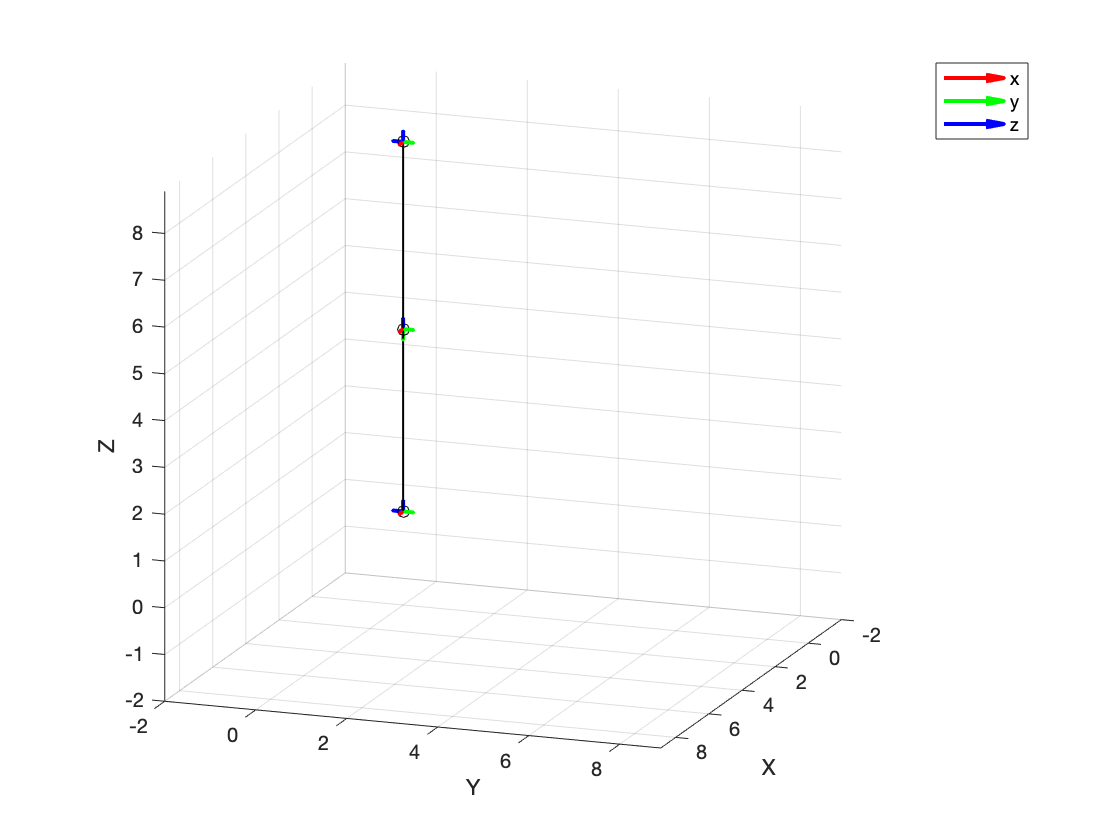


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { d3, d5, q1, q2, q3, q4, q5, q6, q7};

new = { 3.9, 4, 0, 0, 0, 0, 0, 0, 0};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);

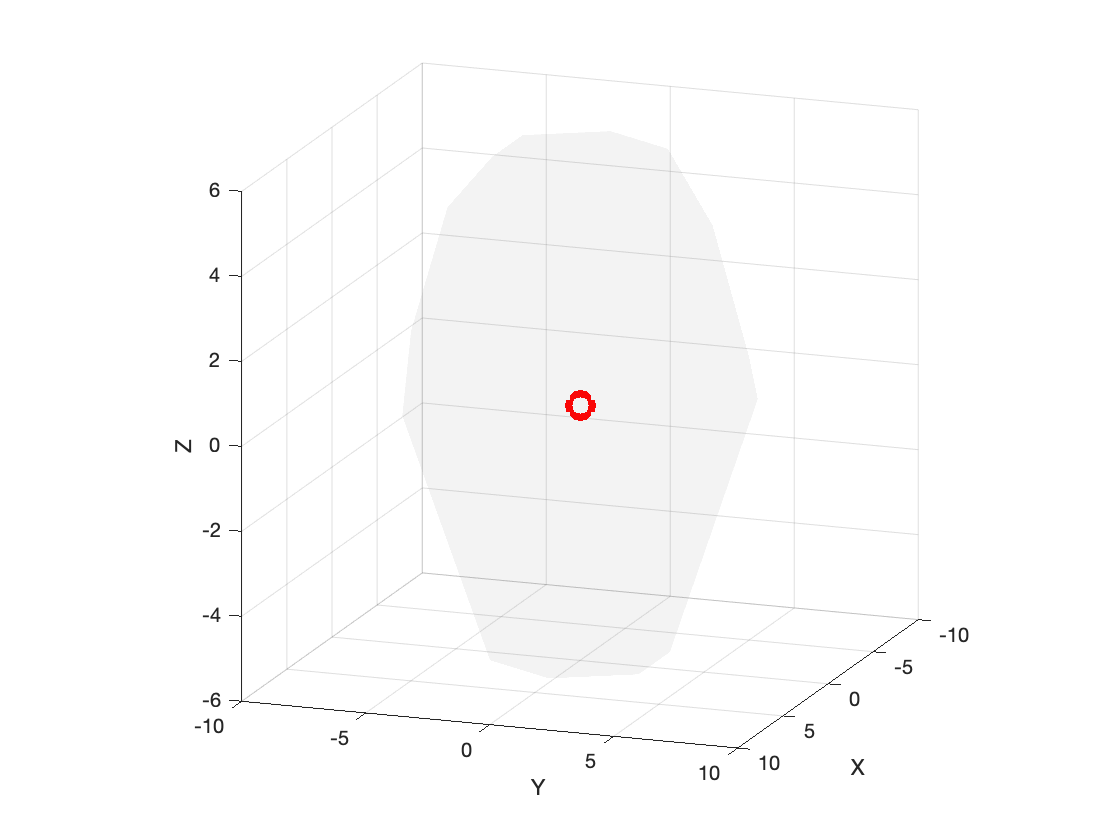


% JOINT LIMITS
t1=linspace(-180,180,4)*pi/180;
t2=linspace(-180,180,4)*pi/180;
t3=linspace(-180,180,4)*pi/180;
t4=linspace(-180,180,4)*pi/180;
t5=linspace(-180,180,4)*pi/180;
t6=linspace(-180,180,4)*pi/180;
t7=linspace(-180,180,4)*pi/180;
[t1,t2,t3,t4,t5,t6,t7]=ndgrid(t1,t2,t3,t4,t5,t6,t7);
old = { d3, d5, q1, q2, q3, q4, q5, q6, q7};
new = { 3.9, 4, t1,t2,t3,t4,t5,t6,t7};

% PLOT WORKSPACE
SR_ROBO.workspace(T_sym,old,new);

# KUKA KR5 Sixx R650 (6R)

disp('KUKA KR5 Sixx R650 (6R)')

KUKA KR5 Sixx R650 (6R)


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = [...
    sym(-pi/2)  0   d1  q1;
    sym(pi)     a2  0   q2;
    sym(-pi/2)  0   d3  q3;
    sym(-pi/2)  0   d4  q4;
    sym(pi/2)   0   0   q5;
    0           0   d6  q6];

SR_ROBO.showDHTable(DH_table_)

    joint_i     alpha_i      a_i       d_i      theta_i
    _______    _________    ______    ______    _______

       1       {'-pi/2'}    {'0' }    {'d1'}    {'q1'} 
       2       {'pi'   }    {'a2'}    {'0' }    {'q2'} 
       3       {'-pi/2'}    {'0' }    {'d3'}    {'q3'} 
       4       {'-pi/2'}    {'0' }    {'d4'}    {'q4'} 
       5       {'pi/2' }    {'0' }    {'0' }    {'q5'} 
       6       {'0'    }    {'0' }    {'d6'}    {'q6'} 



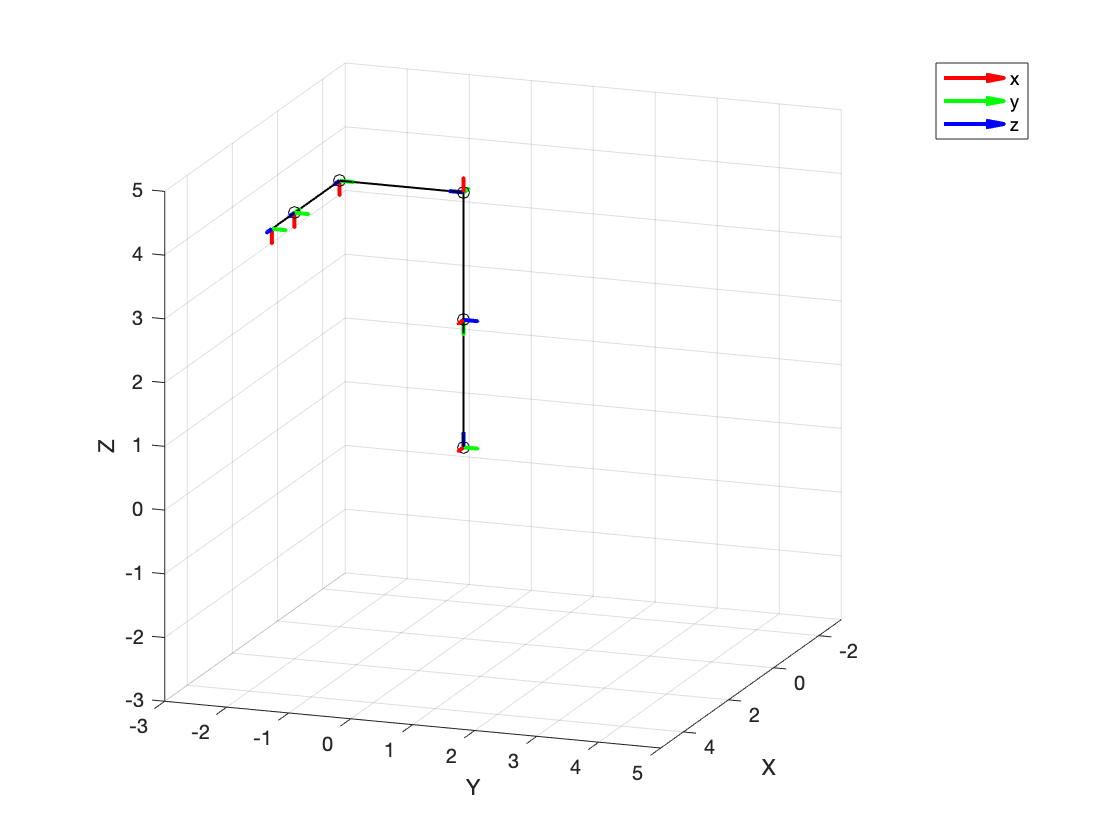


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { a2, d1,  d3, d4, d6, q1, q2, q3, q4, q5, q6};

new = { 2, 2, 2, 2, 1, 0, -pi/2, -pi, 0, 0, 0};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);

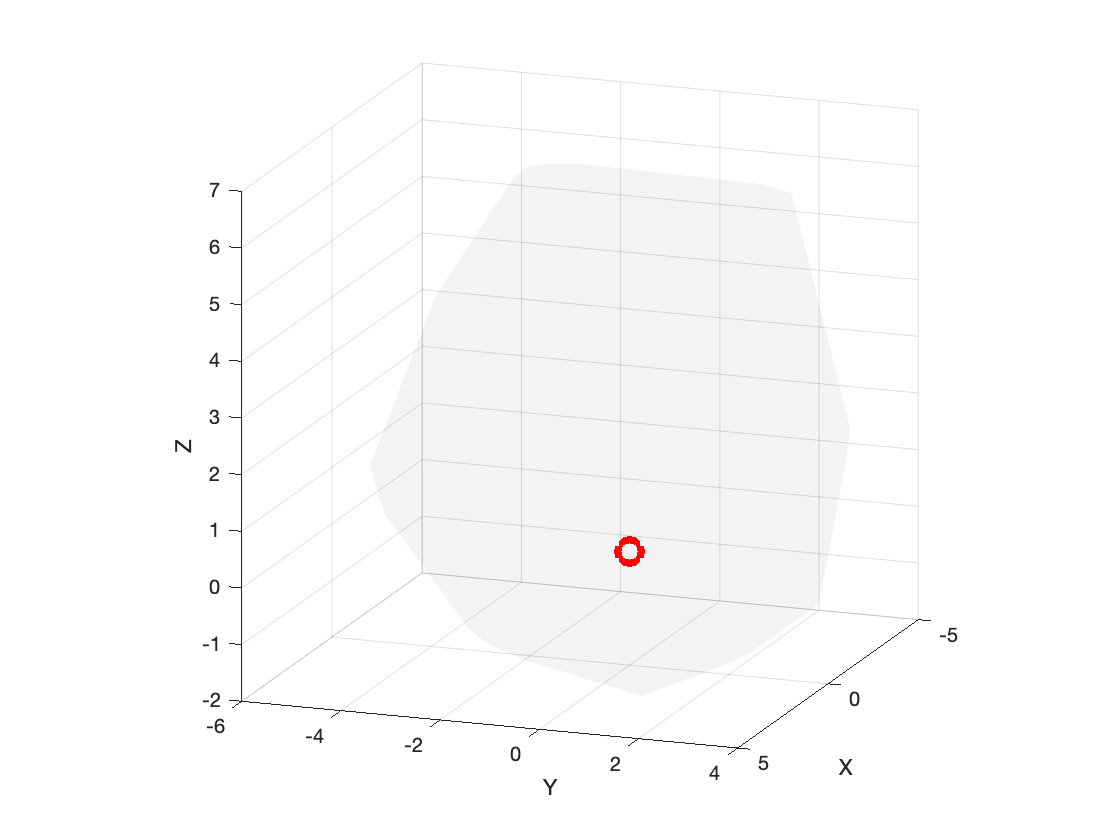


% JOINT LIMITS
t1=linspace(-180,180,4)*pi/180;
t2=linspace(-180,180,4)*pi/180;
t3=linspace(-180,180,4)*pi/180;
t4=linspace(-180,180,4)*pi/180;
t5=linspace(-180,180,4)*pi/180;
t6=linspace(-180,180,4)*pi/180;
[t1,t2,t3,t4,t5,t6]=ndgrid(t1,t2,t3,t4,t5,t6);
old = { a2, d1,  d3, d4, d6, q1, q2, q3, q4, q5, q6};
new = { 2, 2, 2, 2, 1, t1,t2,t3,t4,t5,t6};

% PLOT WORKSPACE
SR_ROBO.workspace(T_sym,old,new);

# EXERCISES

disp('6R example 1 - antropomorphic arm')

6R example 1 - antropomorphic arm


% ALPHA A   D   THETA

% DH MODEL
DH_table_ = [...
    sym(-pi/2)  0   d1  q1;
    0           a2  0   q2;
    sym(pi/2)   0   d3  q3;
    sym(pi/2)   0   d4  q4;
    sym(-pi/2)  0   d5  q5;
    0           0   d6  q6];

SR_ROBO.showDHTable(DH_table_)

    joint_i     alpha_i      a_i       d_i      theta_i
    _______    _________    ______    ______    _______

       1       {'-pi/2'}    {'0' }    {'d1'}    {'q1'} 
       2       {'0'    }    {'a2'}    {'0' }    {'q2'} 
       3       {'pi/2' }    {'0' }    {'d3'}    {'q3'} 
       4       {'pi/2' }    {'0' }    {'d4'}    {'q4'} 
       5       {'-pi/2'}    {'0' }    {'d5'}    {'q5'} 
       6       {'0'    }    {'0' }    {'d6'}    {'q6'} 



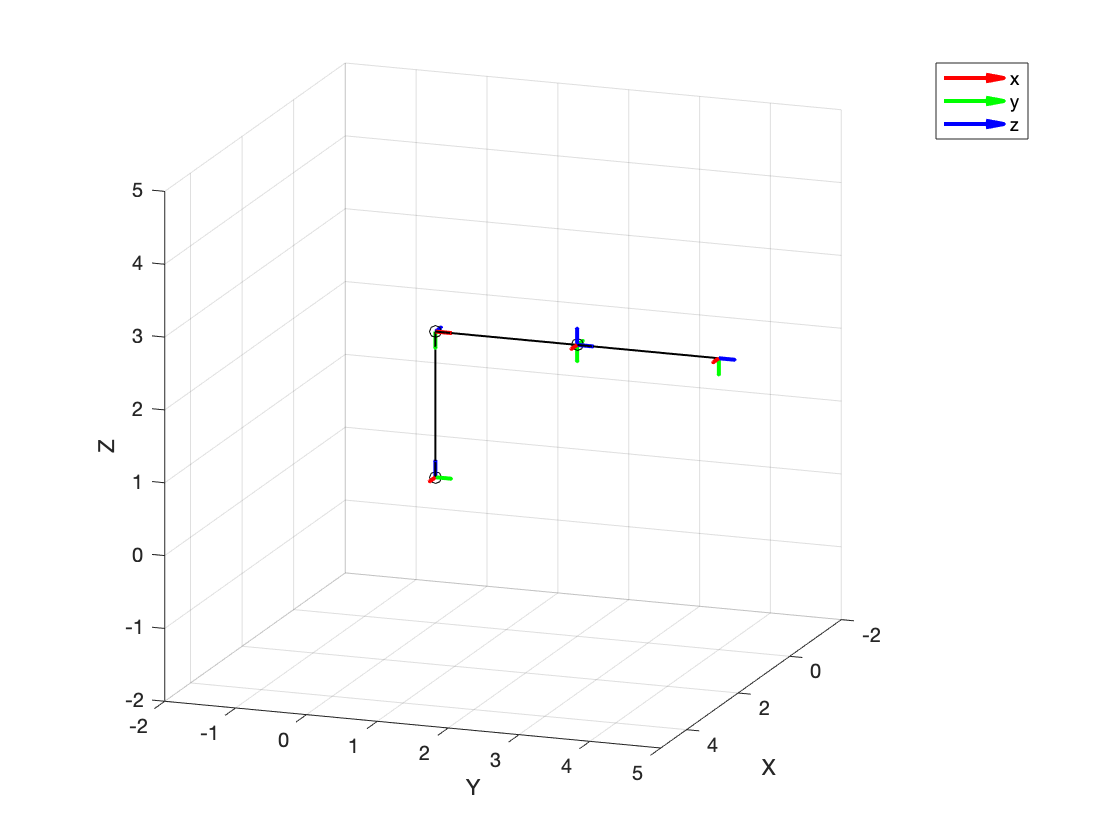


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { a2, d1, d3, d4, d5, d6, q1, q2, q3, q4, q5, q6};

new = { 2, 2, 0, 0, 0, 2, pi/2, 0, pi/2, -pi/2, 0, 0};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);

disp('Midterm classroom test – November 29, 2019')

Midterm classroom test – November 29, 2019


disp('Exercise 2: 6R Universal Robots UR10 - non sph wrist')

Exercise 2: 6R Universal Robots UR10 - non sph wrist



% ALPHA A   D   THETA

% DH MODEL
DH_table_ = [...
    sym(-pi/2)  0   d1  q1;
    0           a2  0   q2;
    sym(pi)     a3  0   q3;
    sym(pi/2)   0   d4  q4;
    sym(-pi/2)  0   d5  q5;
    0           0   d6  q6];

SR_ROBO.showDHTable(DH_table_)

    joint_i     alpha_i      a_i       d_i      theta_i
    _______    _________    ______    ______    _______

       1       {'-pi/2'}    {'0' }    {'d1'}    {'q1'} 
       2       {'0'    }    {'a2'}    {'0' }    {'q2'} 
       3       {'pi'   }    {'a3'}    {'0' }    {'q3'} 
       4       {'pi/2' }    {'0' }    {'d4'}    {'q4'} 
       5       {'-pi/2'}    {'0' }    {'d5'}    {'q5'} 
       6       {'0'    }    {'0' }    {'d6'}    {'q6'} 



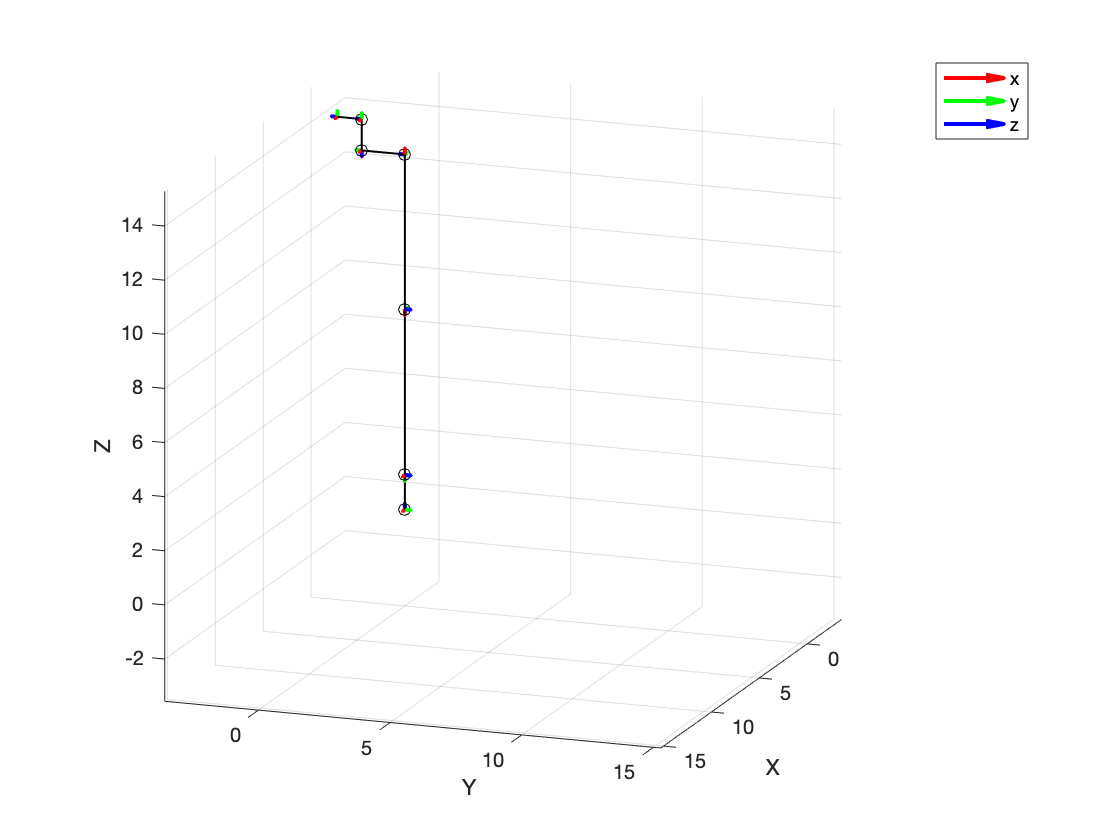


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { a2, a3, d1, d4, d5, d6, q1, q2, q3, q4, q5, q6};

new = { -6.127, 5.716, 1.28, 1.639, -1.157, 0.922, 0, pi/2, pi, -pi/2, 0, 0};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);

disp('Exam - January 7, 2020')

Exam - January 7, 2020


disp('Exercise 1: 7R CESAR - Yaw Roll Pitch wrist')

Exercise 1: 7R CESAR - Yaw Roll Pitch wrist



% ALPHA A   D   THETA

% DH MODEL
DH_table_ = [...
    sym(-pi/2)  0   d1 q1;
    sym(-pi/2)  0   d2 q2;
    sym(pi/2)   0   d3 q3;
    0           a4  0  q4;
    sym(pi/2)   0   0  q5;
    sym(pi/2)   0   0  q6;
    0           0   d7 q7];

SR_ROBO.showDHTable(DH_table_)

    joint_i     alpha_i      a_i       d_i      theta_i
    _______    _________    ______    ______    _______

       1       {'-pi/2'}    {'0' }    {'d1'}    {'q1'} 
       2       {'-pi/2'}    {'0' }    {'d2'}    {'q2'} 
       3       {'pi/2' }    {'0' }    {'d3'}    {'q3'} 
       4       {'0'    }    {'a4'}    {'0' }    {'q4'} 
       5       {'pi/2' }    {'0' }    {'0' }    {'q5'} 
       6       {'pi/2' }    {'0' }    {'0' }    {'q6'} 
       7       {'0'    }    {'0' }    {'d7'}    {'q7'} 



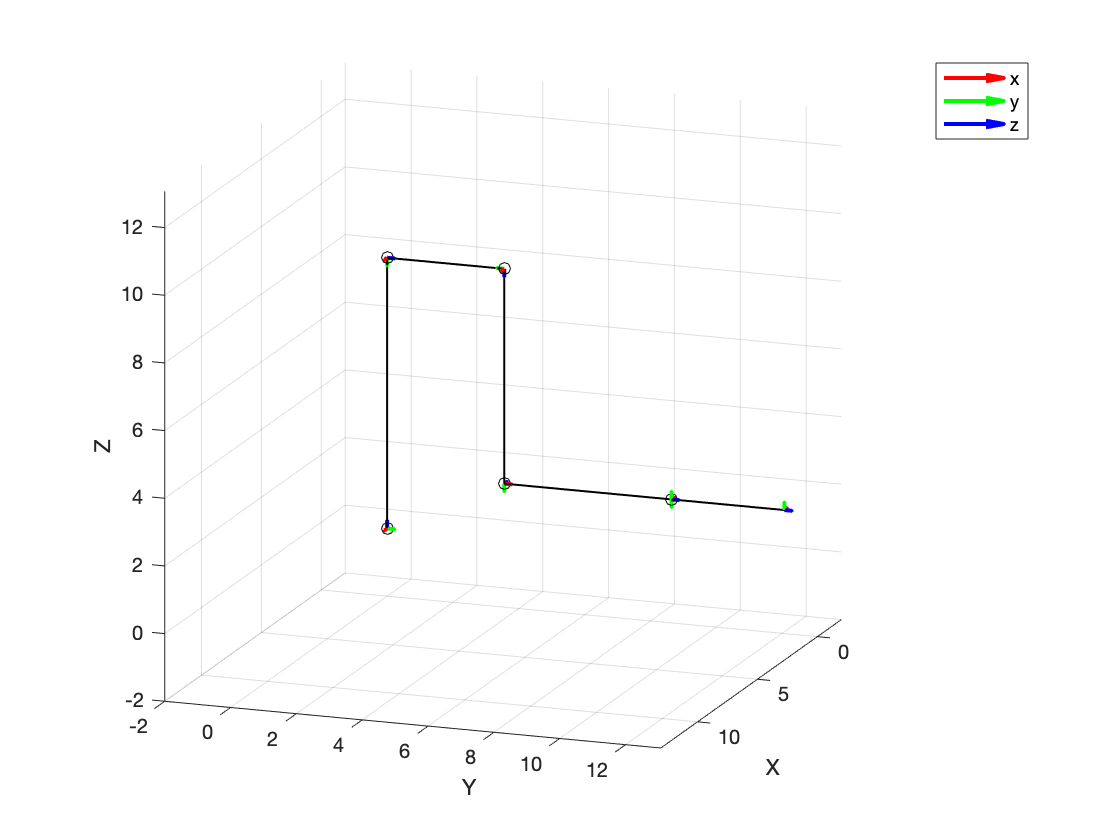


[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,false);

% DIRECT KINEMATIC
old = { d1, d2, d3, a4, d7, q1, q2, q3, q4, q5, q6, q7};

new = { 8, 3.56, 6.35, 5.08, 3.43, 0, 0, -pi/2, 0, 0, pi/2, 0};

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},old,new));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);